## Population Balance Equations: Discrete Sectional Method (DSM)

#### Diffusion controlled growth (for spherical particles with initial radius $r_0 <1\mu m$)


$$\frac{\partial f}{\partial t}+\frac{\partial }{\partial r}\left(\dot{R} f\right)=0$$


initial conditions: $f\left(r,t=0\right)=f^0 \left(r\right)$

boundary conditions: $\dot{R} f\left(r=0,t\right)=0$, $\dot{R} f\left(r=+\infty ,t\right)=0$ 

#### Initial solution


$$f^0 \left(r\right)={\textrm{ar}}^2 \exp \left(-\textrm{br}\right)$$


#### Analytical Solution


$$f\left(r,t\right)=$$

$$\frac{r}{\sqrt{r^2 -2k_G t}}f^0 \left(\sqrt{r^2 -2k_G t}\right)$$


**Growth rate**


$$\dot{R} =\frac{\textrm{dr}}{\textrm{dt}}=\frac{k_G }{r}$$


**Parameters**


$$\begin{array}{l}
a=0\ldotp 108\;\mu m^{-1} {\textrm{cm}}^{-3} \\
b=0\ldotp 60\;\mu m^{-1} \\
k_G =0\ldotp 78\;\mu m^2 s^{-1} 
\end{array}$$


% a and b: distribution parameters
a = 0.108;  % (1/mum/cm3)
b = 0.60;   % (1/mum)

% Growth rate: dr/dt
kG = 0.78;  % growth rate constant (mum2/s)

## Numerical Solution (Discrete Sectional Method)

% Domain of integration
rMax = 30;  % maximum radius (mum)
M = 100;    % number of sections
tf = 20;    % maximum time (s)

% Initial distribution (#/cm3/mum)
r = 0:rMax/M:rMax;
fIn = fInitial(r, a, b);

#### Discrete sections


$$N_i =f_{i+1} \left(r_{i+1} -r_i \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;i=1,\ldotp \ldotp \ldotp ,M$$


% Number of particles (per unit of volume) in each interval (#/cm3)
NIn = zeros(M,1);
for i=1:M
    NIn(i) = fIn(i+1)*(r(i+1)-r(i));
end

#### Discretized equations


$$\frac{{\textrm{dN}}_1 }{\textrm{dt}}=-f_2 {\dot{R} }_2$$



$$\frac{{\textrm{dN}}_i }{\textrm{dt}}=-f_{i+1} {\dot{R} }_{i+1} +f_i {\dot{R} }_i \;\;\;\;\;\;\;\;\;\;\;\;i=2,\ldotp \ldotp \ldotp ,M-1$$



$$\frac{{\textrm{dN}}_M }{\textrm{dt}}=f_M {\dot{R} }_M$$


% Solution of discrete section equations
[t, N] = ode15s(@ODESystem, 0:1:tf, NIn, [], r, kG);
ntimes = length(t);

#### Reconstruct the density function

$f_{i+1}$=$\frac{N_i }{r_{i+1} -r_i }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;i=1,\ldotp \ldotp \ldotp ,M$

% Reconstruction of density function (#/cm3/mum3)
f = zeros(ntimes, M+1);
for i=1:ntimes
    f(i, 2:end) = N(i,:)./(r(2:end)-r(1:end-1));
end

#### Plot solution at t=tf

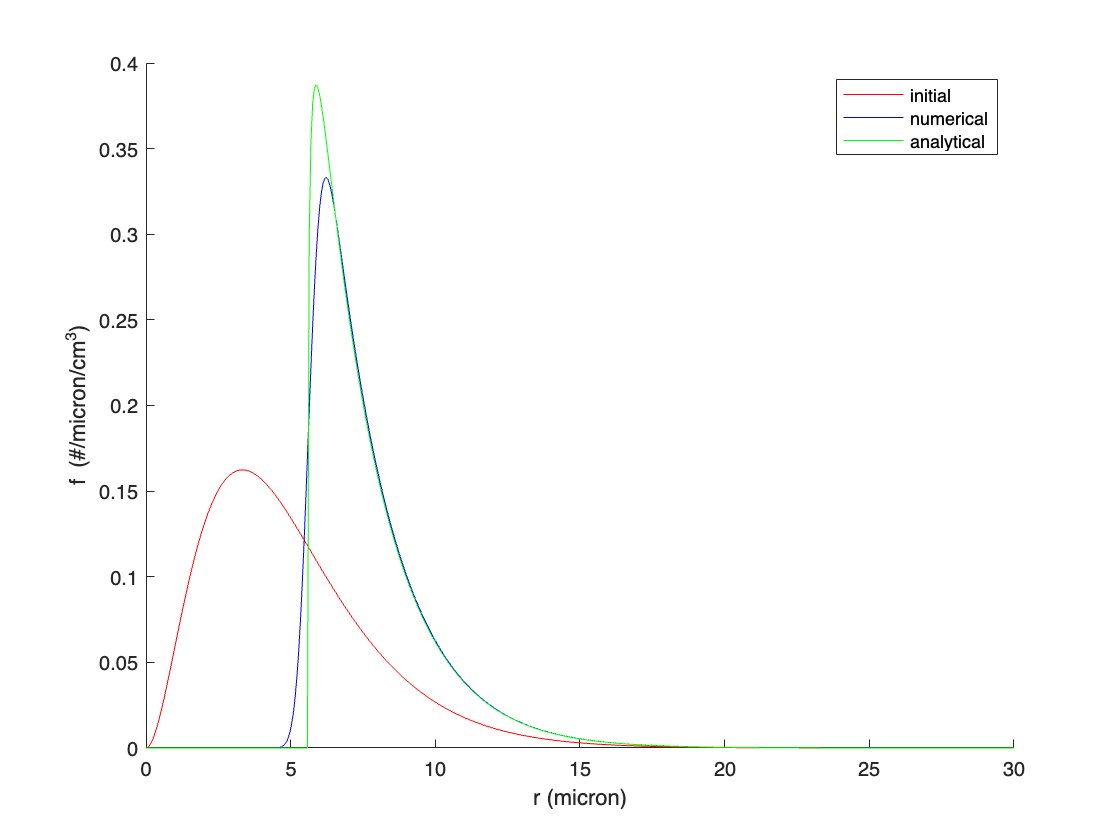

figure; hold on;
plot(r, fIn, 'r');
plot(r, f(end,:),'b');
plot(r, fAnalytical(r, tf, kG, a, b), 'g');
xlabel('r (micron)');
ylabel('f (#/micron/cm^3)');
legend('initial', 'numerical', 'analytical');
hold off;

#### Calculation of moments

% Calculation of moments (initial and final)
m0(1) = Moment(r, fIn, 0);
m0(2) = Moment(r, fIn, 1);
mf(1) = Moment(r, f(end,:), 0);
mf(2) = Moment(r, f(end,:), 1);

fprintf('Time=0 s:  Ntot(#/cm3)=%f Rm(micron)=%f\n', m0(1), m0(2));

Time=0 s:  Ntot(#/cm3)=0.999997 Rm(micron)=4.999912


fprintf('Time=20 s: Ntot(#/cm3)=%f Rm(micron)=%f\n', mf(1), mf(2));

Time=20 s: Ntot(#/cm3)=0.999997 Rm(micron)=7.769062


### Evolution of mean radius

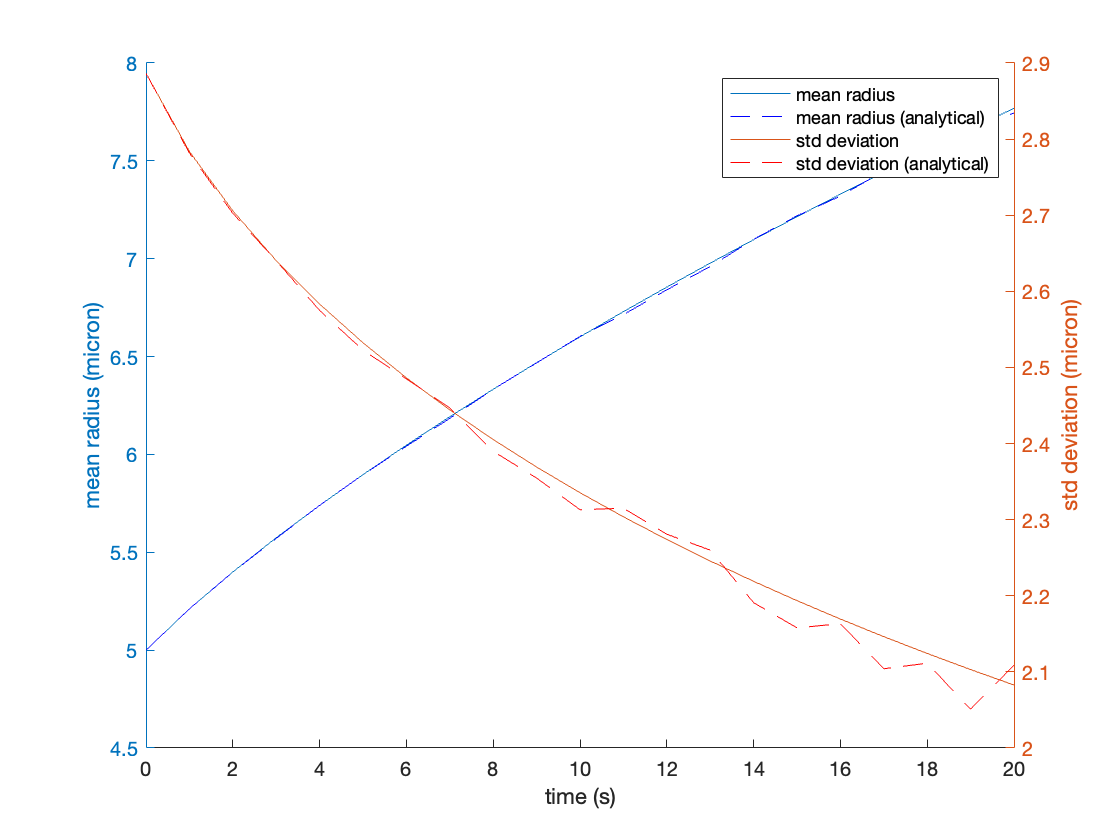

%  Analytical results
muAnalytical1 = zeros(length(t),1);
muAnalytical2 = zeros(length(t),1);
for k=1:length(t)
    muAnalytical1(k) = AnalyticalMoments(1, r, t(k), kG, a, b);
    muAnalytical2(k) = AnalyticalMoments(2, r, t(k), kG, a, b);
end

% Numerical results
m1 = zeros(length(t),1);
m2 = zeros(length(t),1);
for i=1:length(t)
    m1(i) = Moment(r, f(i,:), 1);
    m2(i) = Moment(r, f(i,:), 2);
    
end

figure; hold on;
yyaxis left; ylabel('mean radius (micron)');
plot(t, m1); 
plot(t, muAnalytical1, 'b--');
yyaxis right; ylabel('std deviation (micron)');
plot(t, sqrt(m2-m1.^2)); 
plot(t, sqrt(muAnalytical2-muAnalytical1.^2), 'r--');
xlabel('time (s)'); hold off;
legend('mean radius', 'mean radius (analytical)', 'std deviation', 'std deviation (analytical)');

### Dynamic evolution of density function

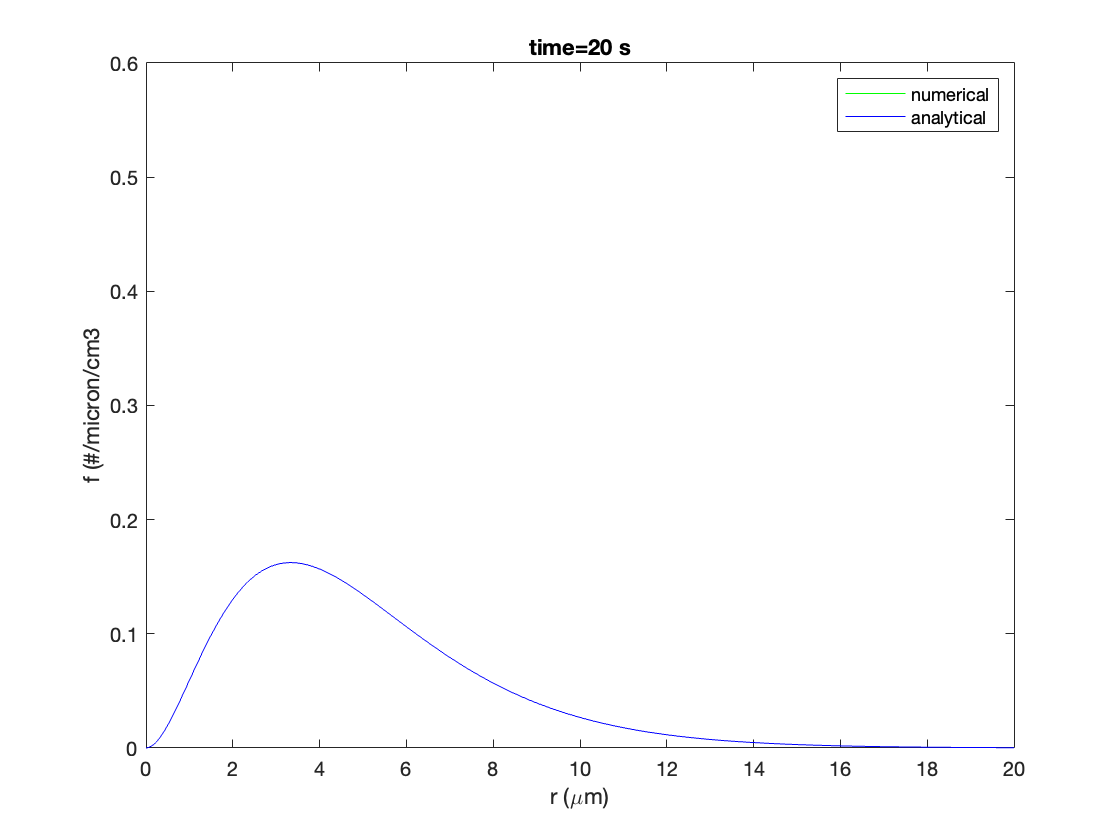

video_name = 'dsm.mp4';
videompg4 = VideoWriter(video_name, 'MPEG-4');
open(videompg4);

figure;
for k=1:length(t)
     hold off;
     plot(r, fAnalytical(r, t(k), kG, a, b), 'g');
     hold on;
     plot(r, f(k,:), 'b');
     hold on;
     xlabel('r (\mum)'); ylabel('f (#/micron/cm3'); title('time=20 s'); 
     xlim([0 20]); ylim([0 0.6]);
     legend('numerical','analytical');
     frame = getframe(gcf);
     writeVideo(videompg4, frame);
end

close(videompg4);


### Functions

function dN = ODESystem(~, N, r, kG)

    M = length(N);

    f = zeros(M+1,1);
    for i=1:M
        f(i+1) = N(i)/(r(i+1)-r(i));
    end

    dN = zeros(M,1);
    dN(1) = -f(2)*Rdot(kG, r(2));
    for i=2:M-1
        dN(i) = -f(i+1)*Rdot(kG, r(i+1)) + f(i)*Rdot(kG, r(i));
    end
    dN(M) = f(M)*Rdot(kG, r(M));

end



function drdt = Rdot(kG, r)

    drdt = kG/r;

end

function f = fAnalytical(r, t, kG, a, b)

    f = zeros(length(r),1);
    for i=1:length(r)
        arg = r(i)^2-2*kG*t;
        if (arg > 0)
            f(i) = r(i)/sqrt(arg).*fInitial(sqrt(arg), a, b);
        end
    end

end

function m = Moment(r, f, order)

    np = length(r);
    m = 0;
    for i=1:np-1
        deltar = r(i+1)-r(i);
        I = 0.50*(f(i+1)*r(i+1)^order+f(i)*r(i)^order);
        m = m + deltar*I;
    end

end


function f = fInitial(r, a, b)

    f = a*(r.^2).*exp(-b*r);

end

function muk = AnalyticalMoments(k, r, t, kG, a, b)

    muk = 0.;
    for j=1:length(r)-1
        deltar = r(j+1)-r(j);
        Ic = 0.50*(r(j+1)^(k)*fAnalytical(r(j+1), t, kG, a, b)+r(j)^(k)*fAnalytical(r(j), t, kG, a, b));
        muk = muk + Ic*deltar;
    end

end